# Grad-CAM热力图可解释性分析

使用Grad-CAM方法，对深度学习图像分类模型进行可解释性分析和显著性分析。

展示神经网络预测出的指定类别，在原始输入图像上的“重点关注区域”。

同济子豪兄 https://space.bilibili.com/1900783

2022-9-12

This example shows Grad-CAM using the `dlgradient` automatic differentiation function to perform the required computations easily. 

## 载入预训练图像分类模型

net = googlenet;

## 神经网络输入图像尺寸

inputSize = net.Layers(1).InputSize(1:2);
inputSize

inputSize =    224   224


## 载入测试图像文件

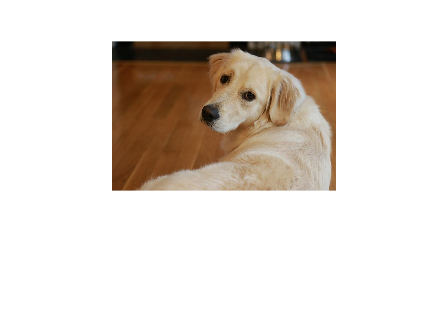

img = imread('sherlock.jpg');
imshow(img)

## 测试图像尺寸

imgSize = size(img);
imgSize

imgSize =    640   960     3


## 缩放图像至神经网络指定输入尺寸

imgResized = imresize(img, inputSize);
size(imgResized)

ans =    224   224     3


## 输入神经网络，执行图像分类预测

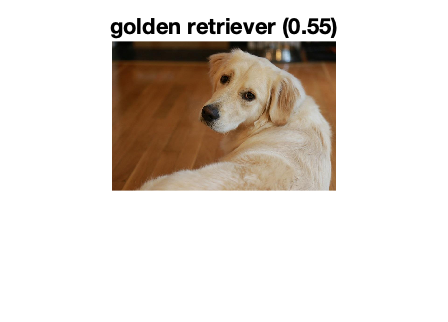

[classfn,score] = classify(net, imgResized);
imshow(img);
title(sprintf("%s (%.2f)", classfn, score(classfn)));

The `gradcam` helper function computes the Grad-CAM map for a `dlnetwork`, taking the derivative of the softmax layer score for a given class with respect to a convolutional feature map. For automatic differentiation, the input image `dlImg` must be a `dlarray`.

type gradcam.m

function [featureMap,dScoresdMap] = gradcam(dlnet, dlImg, softmaxName, featureLayerName, classfn)
[scores,featureMap] = predict(dlnet, dlImg, 'Outputs', {softmaxName, featureLayerName});
classScore = scores(classfn);
dScoresdMap = dlgradient(classScore,featureMap);
end


The first line of the `gradcam` function obtains the class scores and the feature map from the network. The second line finds the score for the selected classification (golden retriever, in this case). `dlgradient` calculates gradients only for scalar-valued functions. So `gradcam` calculates the gradient of the image score only for the selected classification. The third line uses automatic differentiation to calculate the gradient of the final score with respect to the weights in the feature map layer.

To use Grad-CAM, create a `dlnetwork` from the GoogLeNet network. First, create a layer graph from the network.

lgraph = layerGraph(net);

去掉最后一层分类输出层

lgraph = removeLayers(lgraph, lgraph.Layers(end).Name);

Create a `dlnetwork` from the layer graph.

dlnet = dlnetwork(lgraph);

Specify the names of the softmax and feature map layers to use with the Grad-CAM helper function. For the feature map layer, specify either the last ReLU layer with non-singleton spatial dimensions, or the last layer that gathers the outputs of ReLU layers (such as a depth concatenation or an addition layer). If your network does not contain any ReLU layers, specify the name of the final convolutional layer that has non-singleton spatial dimensions in the output. Use the function [`analyzeNetwork`](docid:nnet_ref#mw_8d52b67d-b6b3-4c62-b573-56fdf4dce6a0) to examine your network and select the correct layers. For GoogLeNet, the name of the softmax layer is `'prob'` and the depth concatenation layer is `'inception_5b-output'`.

softmaxName = 'prob';
featureLayerName = 'inception_5b-output';

To use automatic differentiation, convert the sherlock image to a `dlarray`.

dlImg = dlarray(single(img),'SSC');

Compute the Grad-CAM gradient for the image by calling `dlfeval` on the `gradcam` function.

[featureMap, dScoresdMap] = dlfeval(@gradcam, dlnet, dlImg, softmaxName, featureLayerName, classfn);

Resize the gradient map to the GoogLeNet image size, and scale the scores to the appropriate levels for display.

gradcamMap = sum(featureMap .* sum(dScoresdMap, [1 2]), 3);
gradcamMap = extractdata(gradcamMap);
gradcamMap = rescale(gradcamMap);
gradcamMap = imresize(gradcamMap, imgSize(1:2), 'Method', 'bicubic');

Show the Grad-CAM levels on top of the image by using an `'AlphaData'` value of 0.5. The `'jet'` colormap has deep blue as the lowest value and deep red as the highest.

size(gradcamMap)

ans =    640   960


inputSize =    224   224


imgSize(1:2)

ans =    640   960


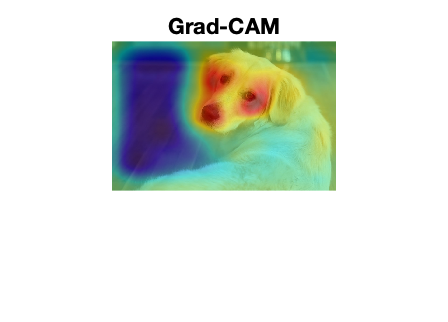

imshow(img);
hold on;
imagesc(gradcamMap,'AlphaData',0.5);
colormap jet
hold off;
title("Grad-CAM");

imshow(img);
hold on;
imagesc(gradcamMap,'AlphaData',0.5);
colormap jet
hold off;
title("Grad-CAM");